%график
%2 задание
clear, clc
y1 = ezplot('cos(x-1)+y - 0.5');
set(y1);

            BusyAction: {'queue'  'cancel'}
         ButtonDownFcn: {}
              Children: {}
              Clipping: {[on]  [off]}
           ContextMenu: {}
             CreateFcn: {}
             DeleteFcn: {}
           DisplayName: {}
                  Fill: {[on]  [off]}
      HandleVisibility: {'on'  'callback'  'off'}
               HitTest: {[on]  [off]}
         Interruptible: {[on]  [off]}
          LabelSpacing: {}
             LevelList: {}
         LevelListMode: {'auto'  'manual'}
             LevelStep: {}
         LevelStepMode: {'auto'  'manual'}
             LineColor: {'none'  'flat'  'auto'}
             LineStyle: {'-'  '--'  ':'  '-.'  'none'}
             LineWidth: {}
                Parent: {}
         PickableParts: {'visible'  'none'  'all'}
              Selected: {[on]  [off]}
    SelectionHighlight: {[on]  [off]}
              ShowText: {[on]  [off]}
                   Tag: {}
              TextList: {}
          TextListMode: {'auto'  'manual'}
     

hold on;
y2 = ezplot('x-cos(y) - 3');
set(y2);

            BusyAction: {'queue'  'cancel'}
         ButtonDownFcn: {}
              Children: {}
              Clipping: {[on]  [off]}
           ContextMenu: {}
             CreateFcn: {}
             DeleteFcn: {}
           DisplayName: {}
                  Fill: {[on]  [off]}
      HandleVisibility: {'on'  'callback'  'off'}
               HitTest: {[on]  [off]}
         Interruptible: {[on]  [off]}
          LabelSpacing: {}
             LevelList: {}
         LevelListMode: {'auto'  'manual'}
             LevelStep: {}
         LevelStepMode: {'auto'  'manual'}
             LineColor: {'none'  'flat'  'auto'}
             LineStyle: {'-'  '--'  ':'  '-.'  'none'}
             LineWidth: {}
                Parent: {}
         PickableParts: {'visible'  'none'  'all'}
              Selected: {[on]  [off]}
    SelectionHighlight: {[on]  [off]}
              ShowText: {[on]  [off]}
                   Tag: {}
              TextList: {}
          TextListMode: {'auto'  'manual'}
     

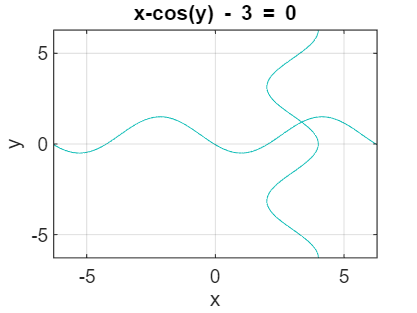

grid on;


%решение
x0 = 1.16; %точки полученные графически
y0 = 3.32; 
x = cos(y0) + 3;
y = 0.5 - cos(x - 1);
e = 0.01; %точность

k = 0; %счетчик итераций
while or((abs(x - x0 ) > e), (abs(y - y0) > e)) %пока точность не будет достигнута
x0 = x;
y0 = y;
x = cos(y) + 3;  
y = 0.5 - cos(x - 1);
k = k + 1;
end
%вывод
disp('Задание 2:');

Задание 2:


disp('Количество итераций:');

Количество итераций:


k   %количество итераций

k = 13

x   %решения

x = 3.3588

y

y = 1.2089


%задание 1
A = [3 1 -1 1
    1 -4 1 -1
    -1 1 4 1
    1 2 1 -5]; 
b = [9; -3; 12; 5];
r=0;
disp('Решение с помощью функции Matlab:');

Решение с помощью функции Matlab:


x = A\b % точное решение 

x =     3.0000
    2.0000
    3.0000
    1.0000


x0 = [1.4;1;2;0.5];
eps = 0.01;
n = length(b);
diagA = diag(A);
A = A-diag(diag(A));
% итерации
err = 10*eps;
while err > eps
  x = (b-A*x0)./diagA;
  err = norm(x-x0);
  x0 = x;
  r=r+1;
end
disp('Задание 1:');

Задание 1:


x % result

x =     3.0025
    2.0028
    3.0021
    1.0013


disp('Кол-во итераций:');

Кол-во итераций:


r

r = 12